## Training statistics of different agent strategies

The startegies are the followings:

- Continuous action space with offset and range

- Continuous action space with offset only

- Discrete action space with offset and range

- Discrete action space with offset only

Results are stored in diffeent folders:

folder(1) = "savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\";
folder(2) = "savedAgents\SAC_PassCarModelX_RL_norm_offset_cont_4w_lat_batch\";
folder(3) = "savedAgents\SAC_PassCarModelX_RL_norm_offset_range_disc_4w_lat_batch\";
folder(4) = "savedAgents\SAC_PassCarModelX_RL_norm_offset_disc_4w_lat_batch\";

titles(1) = "Continues with noise";
titles(2) = "Continues without noise";
titles(3) = "Discrete with noise";
titles(4) = "Discrete without noise";

function es = LoadTrainingResult(trainingResultFile)
    load(trainingResultFile, "trainingResults");
    es = trainingResults.EvaluationStatistic(~isnan(trainingResults.EvaluationStatistic));
end

for i=1:4
    for j=1:5
        filename = sprintf('TrainingResult_%d.mat', j);
        filename_w_folder = folder(i) + filename;
        %disp(filename_w_folder);
        all_es(i,:,j) = LoadTrainingResult(filename_w_folder);
    end
end

### plot 1 by 4 statistics

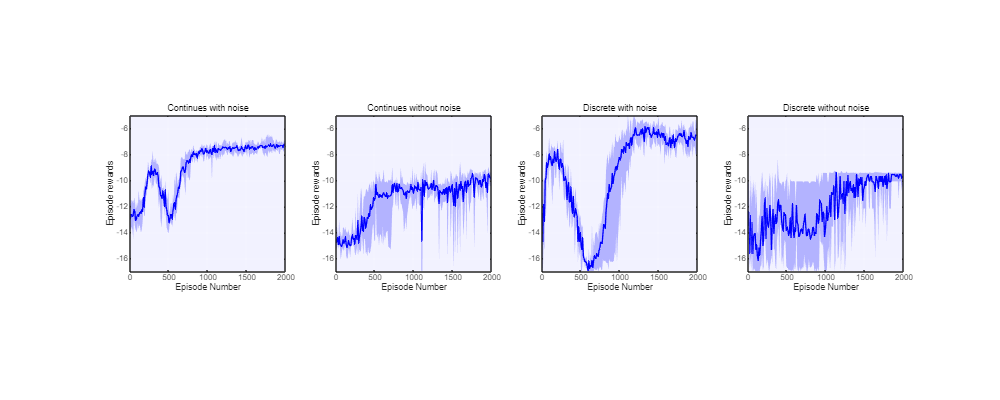

figure

for i=1:4
    subplot(1,4,i);


    % Compute statistics
    es = squeeze(all_es(i,:,:));
    meanVals = mean(es, 2);  % Mean across columns
    minVals = min(es, [], 2);  % Min across columns
    maxVals = max(es, [], 2);  % Max across columns
    
    % Plot
    x = 1:2000;
    x_sampled = x(1:10:end);


mv = -6.4728

mi = 377

episode_num = 177

batch_idx = 2

mv = -8.5724

mi = 315

episode_num = 115

batch_idx = 2

mv = -4.9932

mi = 919

episode_num = 119

batch_idx = 5

mv = -8.3032

mi = 439

episode_num = 39

batch_idx = 3

    % Shaded area between min and max
    fill([x_sampled, fliplr(x_sampled)], [maxVals', fliplr(minVals')], [0.7 0.7 1], 'EdgeColor', 'none');    
    hold on;

    % Plot mean line
    plot(x_sampled, meanVals, 'b', 'LineWidth', 1);
    hold off;

    xlabel('Row Index');
    ylabel('Value');
    %title('Mean with Min-Max Band');
    %legend('Min-Max Band', 'Mean');
    grid on;
    
    hold off;
    xlabel('Episode Number');
    ylabel('Episode rewards');
    ylim([-17 -5])
    title(titles(i), FontWeight="normal");

    axis square;

    ax = gca;
    ax.FontSize = 6;    
    ax.Color = [0.95 0.95 1];
    ax.GridColor = [1 1 1];
    
    %ax.XColor = 'none';
    %ax.YColor = 'none';
end
set(gcf, 'Position', [10, 10, 1000, 400]);  % [left, bottom, width, height]

f = gcf;
exportgraphics(f, 'SAC_all_statistics.pdf', 'ContentType', 'vector');

## Performance results

Select the best agents for all four variants from all trainings

for i=1:4
    es = squeeze(all_es(i,:,:));
    [mv, mi] = max(es(:))
    [episode_num, batch_idx] = ind2sub(size(es), mi)
    subfolder = sprintf("savedAgents_%d\\", batch_idx);
    agentName = sprintf("Agent%d.mat", episode_num*10);
    agents(i) = folder(i) + subfolder + agentName;
end

Prepare simulation for best agent operations

fr_max(1) = 20;
fr_max(2) = 0;
fr_max(3) = 20;
fr_max(4) = 0;

ts_(1) = 0.1;
ts_(2) = 0.01;
ts_(3) = 0.1;
ts_(4) = 0.01;

actionInfo(1) = rlNumericSpec([8 1], 'UpperLimit', [1; 1; 1; 1; 1; 1; 1; 1], 'LowerLimit', [-1; -1; -1; -1; -1; -1; -1; -1]);

actionInfo(2) = rlNumericSpec([4 1], 'UpperLimit', [1; 1; 1; 1], 'LowerLimit', [-1; -1; -1; -1]);

[offsets, ranges] = ndgrid([-1 -0.8 -0.6 -0.4 -0.2 0 0.2 0.4 0.6 0.8 1], [-1 -0.5 0 0.5 1]);
action_pairs = [offsets(:) ranges(:)];
actionInfo(3) = rlFiniteSetSpec(num2cell(action_pairs, 2));

actionInfo(4) = rlFiniteSetSpec([-1 -0.8 -0.6 -0.4 -0.2 0 0.2 0.4 0.6 0.8 1]);


addpath("Config")
addpath("Driveline")
addpath("SI")
addpath("Vehicle")


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 8.7266s


mdl = "PassCarModel_RL_config";
open_system(mdl);

% Fuzzing noise offset in the interval of 
FO_max = 50;

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 7.5568s


FO_min = 0;

% Fuzzing noise variation in the range of 
% FR_max = 20;  --> define for each scenario
FR_min = 0;

% Reward deceleration component
DecelR = 0;
% Reward wheel speed deviation
ODevR = 0;

% agent and environment interaction time periods
% Ts = 0.1;   --> define for each scenario

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.83942s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.84682s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.82943s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.84018s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.85454s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.86253s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.82556s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 0.849s



% total episode time
Tf = 20;


Auxiliry function for generation of an environment

function env = generateEnvironment(actionInfo, mdl)
    obsInfo = rlNumericSpec([5 1]);    
    env = rlSimulinkEnv(mdl, mdl + "/Agent/RL Agent", obsInfo, actionInfo, 'UseFastRestart', 'on');    
    env.ResetFcn = @(in)MyResetFunction(in);
end

Determine the ABS braking start point

function pcmOP = storeReferencePoint(mdl)
    % save the operation point at the beginning of ABS braking
    simIn = Simulink.SimulationInput(mdl);
    simIn = setModelParameter(simIn,"SaveFinalState","on");
    simIn = setModelParameter(simIn,"SaveOperatingPoint","on");
    simIn = setModelParameter(simIn,"StopTime","11.7");
    simIn = setBlockParameter(simIn, mdl + "/Agent/StoppingCondition", Value="-100");
    out = sim(simIn);
    pcmOP = out.xFinal;
    save("PassCarModel_Final_OperationPoint.mat", "pcmOP");
end

### Baseline braking

load(agents(1));
FR_max = fr_max(1);
Ts = ts_(1);
agent = saved_agent;
pcmOP = storeReferencePoint(mdl);

simIn = Simulink.SimulationInput(mdl);
simIn = simIn.setInitialState(pcmOP);
simIn = setBlockParameter(simIn, mdl + "/Agent/Policy/Fuzzing", Value="0");
baseLineOutput = sim(simIn);

### Four scenarios

for i=1:4
    load(agents(i));    
    FR_max = fr_max(i);
    Ts = ts_(i);
    agent = saved_agent;
    simOptions = rlSimulationOptions(MaxSteps=500);    
    agent.UseExplorationPolicy = false;    
    env = generateEnvironment(actionInfo(i), mdl);
    storeReferencePoint(mdl);
    experience(i) = sim(env, agent, simOptions);
end

### Plot performace results

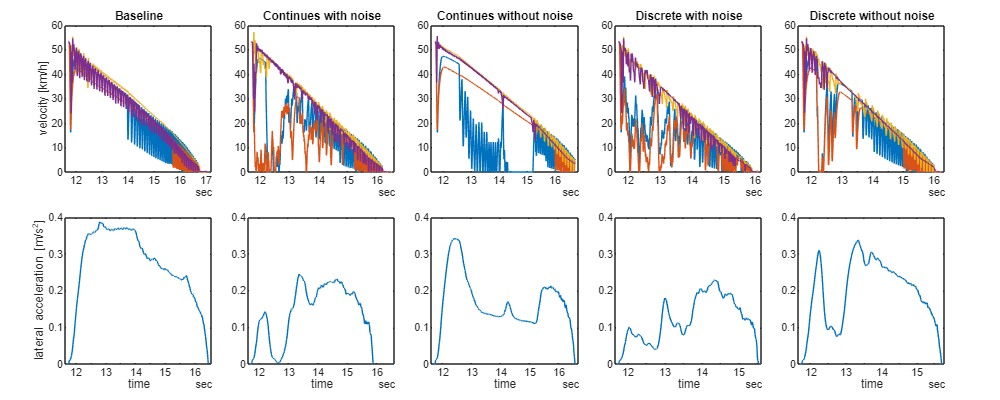

tiledlayout(2, 5, 'Padding', 'compact', 'TileSpacing', 'compact');
%tiledlayout(2, 5);

nexttile;

o = timeseries2timetable(baseLineOutput.logsout.getElement("Omega").Values);
%subtightplot(2,5, 1);
plot(o.Time, o{:,1});
ylim([0 60]);
axis square;
ylabel('velocity [km/h]');
title('Baseline');
ax = gca;
ax.FontSize = 8;    

for i=1:4
    nexttile;
    o = timeseries2timetable(experience(i).SimulationInfo(1).logsout.getElement("Omega").Values);
    plot(o.Time, o{:,1});
    ylim([0 60]);
    axis square;  
    title(titles(i));
    ax = gca;
    ax.FontSize = 8;    
end

nexttile;
ala = timeseries2timetable(baseLineOutput.logsout.getElement("AvgLatAcc").Values);
plot(ala.Time, ala{:,1});
ylim([0 0.4]);
axis square;
ylabel('lateral acceleration [m/s^2]');
xlabel('time');
ax = gca;
ax.FontSize = 8;    

for i=1:4
    nexttile;
    ala = timeseries2timetable(experience(i).SimulationInfo(1).logsout.getElement("AvgLatAcc").Values);
    plot(ala.Time, ala{:,1});
    ylim([0 0.4]);
    axis square;    
    ax = gca;
    ax.FontSize = 8;    
    xlabel('time');
end


set(gcf, 'Position', [100, 100, 1000, 400]);  % [left, bottom, width, height]

f = gcf;
exportgraphics(f, 'SAC_all_performance.pdf', 'ContentType', 'vector');

### Wheel speeds with noises

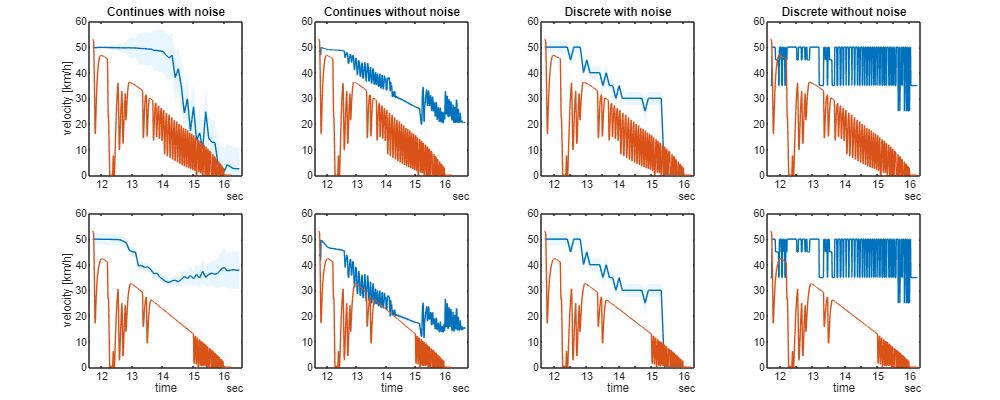

figure;
tiledlayout(2, 4, 'Padding', 'compact', 'TileSpacing', 'compact');

for i=1:4

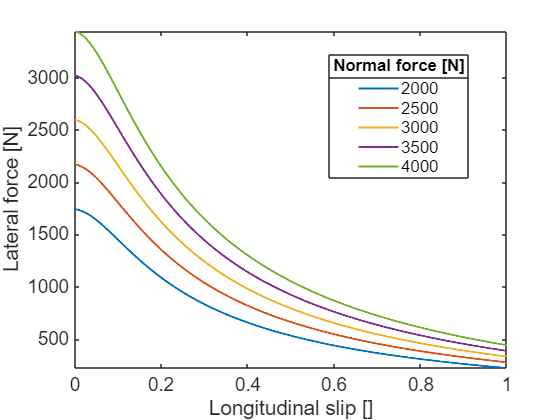

    si = experience(i).SimulationInfo(1);
    tt = timeseries2timetable(si.logsout.getElement("FuzzingAction").Values.FuzzingOffset);
    tr = timeseries2timetable(si.logsout.getElement("FuzzingAction").Values.FuzzingRange);
    
    FL =  tt{:,1}(:,1);
    FL_u = FL + tr{:,1}(:,1)/2;
    FL_l = FL - tr{:,1}(:,1)/2;
    FL_l(FL_l < 0) = 0;
        

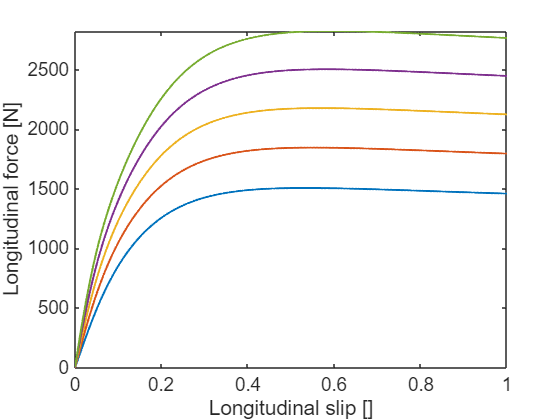

    nexttile;
    hold on;
    fill([tt.Time', fliplr(tt.Time')], [FL_l', fliplr(FL_u')], [0.7 0.9 1], 'EdgeColor', 'none', FaceAlpha=0.3); % shaded band
    plot(tt.Time, tt{:,1}(:,1));
    plot(o.Time, o{:,1}(:,1));
    title(titles(i));
    axis square;
    box on;

    ax = gca;
    ax.FontSize = 8;    
    if i == 1
        ylabel('velocity [km/h]');
    end
    hold off;
        
end
for i=1:4
    si = experience(i).SimulationInfo(1);
    tt = timeseries2timetable(si.logsout.getElement("FuzzingAction").Values.FuzzingOffset);
    tr = timeseries2timetable(si.logsout.getElement("FuzzingAction").Values.FuzzingRange);
        
    FR =  tt{:,1}(:,2);
    FR_u = FR + tr{:,1}(:,2)/2;
    FR_l = FR - tr{:,1}(:,2)/2;
    FR_l(FR_l < 0) = 0;
            
    nexttile;
    hold on;
    fill([tt.Time', fliplr(tt.Time')], [FR_l', fliplr(FR_u')], [0.7 0.9 1], 'EdgeColor', 'none', FaceAlpha=0.3); % shaded band
    plot(tt.Time, tt{:,1}(:,2));
    plot(o.Time, o{:,1}(:,2));
    axis square;
    box on;
    ax = gca;
    ax.FontSize = 8;    
    if i == 1
        ylabel('velocity [km/h]');
    end
    xlabel('time');
    hold off;
end
set(gcf, 'Position', [100, 100, 1000, 400]);  % [left, bottom, width, height]

f = gcf;
exportgraphics(f, 'SAC_all_wheelspeeds.pdf', 'ContentType', 'vector');

### Create figures for wheel dynamics

tm = tireModel.builtin("Light passenger car 205/60R15");
plot(tm, "Direction", "kappa", "DataVariableNames", ["kappa"; "Fy"], "Magnitude", [0; 1], "Fz", [2000; 2500; 3000; 3500; 4000], "alpha", -0.2);
title("");
ax = gca;
ax.FontSize = 14;
f = gcf;
exportgraphics(f, 'LateralForce_Slip.pdf', 'ContentType', 'vector');

plot(tm, "Direction", "kappa", "DataVariableNames", ["kappa"; "Fx"], "Magnitude", [0; 1], "Fz", [2000; 2500; 3000; 3500; 4000], "alpha", -0.2);
title("");
legend off;
ax = gca;
ax.FontSize = 14;    
f = gcf;
exportgraphics(f, 'LongitudinalForce_Slip.pdf', 'ContentType', 'vector');